%Sarwajeet Pratap Singh
%PRN: 20220802013


Sarwajeet Pratap Singh

PRN: 20220802013


clc;
clear;
close all;
N=7;
c=[0 0 1 0 1 1 1];

% Binary to polar mapping
for i=1:length(c)
    if c(i)==0
        cm(i)=-1;
    else
        cm(i)=1;
    end
end
 
%Information bearing signal
 
b=randi([0 1],1,2);
%DSSS baseband mapping
m=[];
for k=1:length(b)
   if b(k)==0
       mm=-cm;
   else
       mm=cm;
   end
   m=[m mm];
end
 
% NRZ pulse Shaping
i=1;
l=1/N;  % Chip duration 
S=700;  % sample per bit
t=0:1/S:length(b)-1/S; %time
 
for j= 1:length(t)
    if t(j)<=l
        y(j)=m(i);
    else
        i=i+1;
        l=l+1/N;
    end
end


Sarwajeet Pratap Singh

PRN: 20220802013

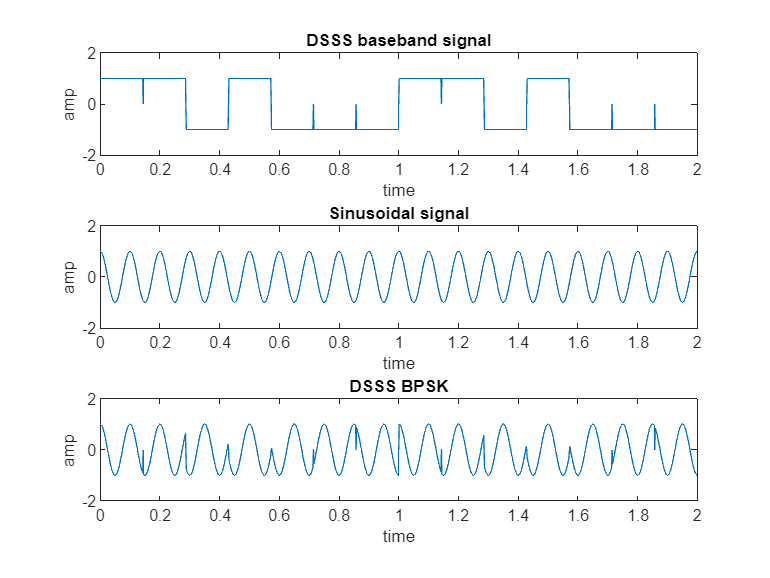

figure(1);
subplot(311);
plot(t,y);
axis([0 length(b) -2 2]);
xlabel('time');
ylabel('amp');
title('DSSS baseband signal')
 
% Carrier
c1=cos(2*pi*10*t);
subplot(312);
plot(t,c1);
axis([0 length(b) -2 2]);
xlabel('time');
ylabel('amp');
title('Sinusoidal signal')
 
% DSSS BPSk
x=y.*c1;
subplot(313);
plot(t,x);
axis([0 length(b) -2 2]);
xlabel('time');
ylabel('amp');
title('DSSS BPSK')